Linear Programming Multicriteria

a = 0.5;
T1 = [2, 1, -1, 0;
    1, 1, 0, -1;
    -2, -1, -1, 0;
    -1, -1, 0, -1];
T2 = [1, 0, 0, 0, -1, 0;
      0, 1, 0, 0, 0, -1;
      -1, 0, 0, 0, -1, 0;
      0, -1, 0, 0, 0, -1];
global A;
A = [T1 zeros(4, 2); T2];
global b;
b = [1; 0; -1; 0; 0; 0; 0; 0];

LP solution

res = optimumLP(0.5);

Optimal solution found.



fprintf("LP solution:\n")

LP solution:


disp(res)

    0.5000
         0
         0
    0.5000
    0.5000
         0



Pareto front curve

a1 = 0 : 0.01 : 1;
[f1, f2] = arrayfun(@paretoFrontCurve, a1);

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solu

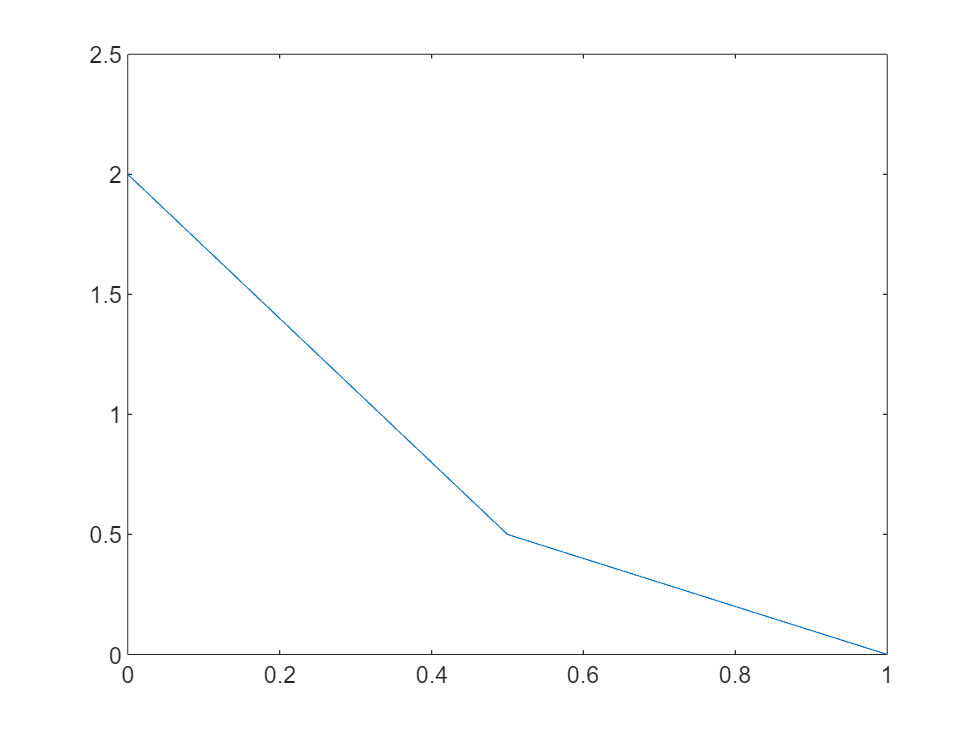

figure
plot(f1, f2)

function res = optimumLP(a)
    %objective function
    global A;
    global b;
    F = [0; 0; a; a; 1-a; 1-a];
    res = linprog(F, A, b);
end

function [f1, f2] = paretoFrontCurve(a)
    A = [2 1; 1 1];
    b = [1; 0];
    res = optimumLP(a);
    x = res(1:2);
    f1 = norm(A*x - b, 1);
    f2 = norm(x, 1);
end